clc; clear; close all;
rng(1);

nrep = 50;
ncoex_vec = zeros(1, nrep);
row_tot_sd = zeros(1, nrep);

for k = 1:nrep
    k
    nspec = 10;
    nm = 3;
    np = 5;
    p_length = 10;

    polys = zeros(np, nm);
    for i = 1:np
        polys(i, :) = create_poly(p_length, nm);
    end
    
    cons_traits_mono = rand(nspec, nm);
    cons_traits_mono = cons_traits_mono ./ sum(cons_traits_mono, 2);    
    
    C = zeros(nspec, np);
    for i = 1:nspec
        C(i, :) = sum((polys' .* cons_traits_mono(i, :)')', 2);
    end
    C = (C * nm) / 50;
    
    params.nspec = nspec;
    params.np = np;
    params.alpha = 0 * ones(nspec, 1);
    params.r = 500 * ones(np, 1);
    params.K = ones(np, 1);
    params.m = 0.2 * ones(nspec, 1);
    params.C = C;
    
    init_abuns = ones(1, params.nspec) * 5;
    init_res = ones(1, params.np) * 5;
    init_state = [init_abuns, init_res];
    
    tspan = [0 10000];
    [t, sim] = ode45(@(t, y) macarthur_eqns(t, y, params), tspan, init_state);
    
    eql = sim(end, :);
    eql_abuns = eql(1:nspec);
    num_coexist = sum(eql_abuns > 0.1);
    
    row_tot_sd(k) = std(sum(C,2));
    ncoex_vec(k) = num_coexist;
end

k = 1

k = 2

k = 3

k = 4

k = 5

k = 6

k = 7

k = 8

k = 9

k = 10

k = 11

k = 12

k = 13

k = 14

k = 15

k = 16

k = 17

k = 18

k = 19

k = 20

k = 21

k = 22

k = 23

k = 24

k = 25

k = 26

k = 27

k = 28

k = 29

k = 30

k = 31

k = 32

k = 33

k = 34

k = 35

k = 36

k = 37

k = 38

k = 39

k = 40

k = 41

k = 42

k = 43

k = 44

k = 45

k = 46

k = 47

k = 48

k = 49

k = 50

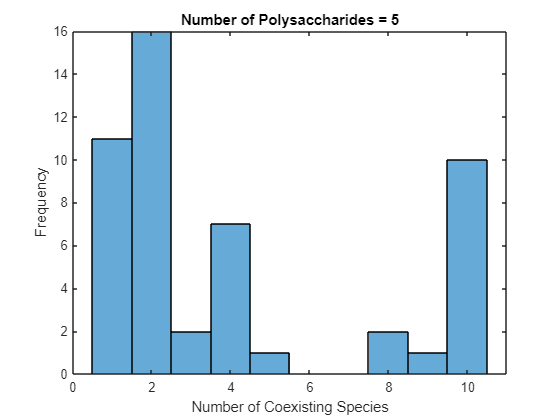


figure;
histogram(ncoex_vec);
title(['Number of Polysaccharides = ', num2str(np)]);
xlabel('Number of Coexisting Species');
ylabel('Frequency');


corr(row_tot_sd(:), ncoex_vec(:), type = 'Pearson')

ans = -0.5493

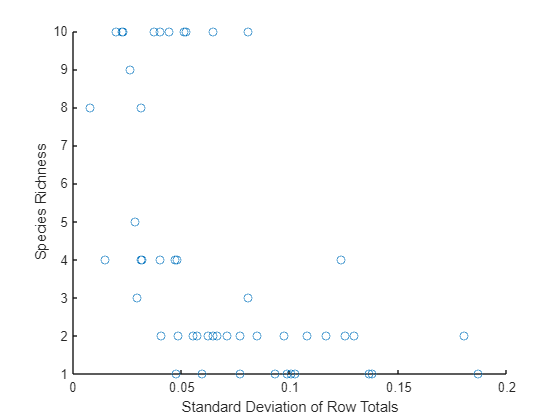

scatter(row_tot_sd, ncoex_vec)
xlabel('Standard Deviation of Row Totals');
ylabel('Species Richness');

function counts = create_poly(p_length, nm)
    vec = randi(nm, 1, p_length);
    counts = histcounts(vec, 1:(nm+1));
end

function dydt = macarthur_eqns(~, state, params)
    N = state(1:params.nspec);
    R = state((params.nspec + 1):end);

    dNdt = params.alpha + N .* ((params.C * R) - params.m);
    dRdt = R .* (params.r .* (1 - R ./ params.K) - (params.C' * N));
    
    dydt = [dNdt; dRdt];
end